# Metodi iterativi per la risoluzione di sistemi lineari

Vogliamo risolvere un sistema lineare del tipo $Ax=b$ mediante il metodo di Jacobi.

## Introduzione

Scegliamo come matrice dei coefficienti$A \in\mathbb{R}^{n\times n}$ la matrice tridiagonale sparsa ottenuta dalla discretizzazione mediante il metodo delle differenze finite del problema di Poisson. Si tratta di una matrice a dominanza diagonale stretta, condizione sufficiente per garantire la convergenza del metodo di Jacobi.

clc
clear
n = 74;
A = distributed(gallery('poisson', n));

Scegliamo come vettore-colonna dei termini noti $b \in \mathbb{R}^N$


$$b = \sum_ {A_{i} \in J} A_{i}$$


dove $J = \{A_{1}, A_{2}, ..., A_{N}\}$denota l'insieme delle colonne della matrice $A$.

b = sum(A,2);

È possibile dimostrare che la soluzione del sistema $x_\text{exact} \in \mathbb{R}^n$ sia pari a


$$x_\text{exact} = [1, 1, ...,1]^T$$


xExact = ones(n^2,1,'distributed');

## Metodo di Jacobi parallelo

Come primo tentativo, risolviamo il sistema con il metodo di Jacobi, un metodo per la risoluzione di sistemi lineari che ad ogni passo genera una serie di soluzioni approssimate per $x_\text{exact}$.

La funzione `pjm` appartenente al Parallel Jacobi Method Toolbox fornisce un'implementazione parallela del metodo di Jacobi, che restituisce in output una lista di parametri tra cui figurano

- `xJM:` la soluzione approssimata per il sistema $Ax=b$;

- `flagJM`: un flag indicante lo stato di uscita dall'esecuzione del metodo di Jacobi;

- `resvecJM`: un vettore in cui ciascun elemento corrisponde al residuo normalizzato al termine di ogni iterazione, calcolato come  $$ \frac{|| b-Ax ||}{ || b ||}$$.  Si tratta di una metrica indicante l'accuratezza della soluzione calcolata tra un'iterazione e la successiva.

Inoltre, il criterio di arresto del metodo dipende da due ulteriori parametri: `maxit`, il numero massimo di iterazioni, e `tol` rappresentante l'accuratezza della soluzione trovata al termine dell'algoritmo. Nel caso in esame,

`tol` $=10^{-6}$

`maxit` $=100$

tJM_1 = tic;
[xJM_1,flagJM_1,relresJM_1,iterJM_1,resvecJM_1] = pjm(A,b);
tJM_1 = toc(tJM_1);
fprintf("Elapsed time for pjm: %f sec.", tJM_1)

Elapsed time for pjm: 24.161318 sec.

Procediamo con il calcolo dell'errore assoluto `errCG` tra le componenti corrispondenti di $x_\text{exact}$ ed `xCG.`

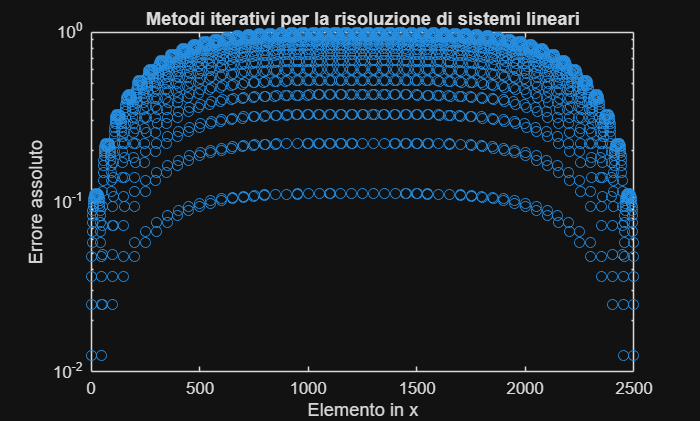

errJM_1 = abs(xExact - xJM_1);

figure(1)
semilogy(errJM_1,'o');
title('Metodi iterativi per la risoluzione di sistemi lineari');
ylabel('Errore assoluto');
xlabel('Elemento in x');

## Metodo di Jacobi classico

Ora risolviamo il sistema $Ax=b$ considerato in precedenza attraverso un'implementazione classica del metodo di Jacobi, in modo da valutare l'effetto sulle prestazioni dovuto alla parallelizzazione dell'algoritmo. 

Ovviamente tutti gli argomenti in input non devono essere più distribuiti sui diversi *worker, *non trattandosi di un problema di calcolo parallelo.

A = gallery('poisson', n);
b = sum(A,2);

Nel caso in esame,

`tol` $=10^{-14}$

`maxit` $=10000$

La funzione s`jm` fornisce un'implementazione classica del metodo di Jacobi, restituendo in output una lista di parametri tra cui figurano `xJM,` `flagJM` e `resvecJM`, con un analogo significato rispetto a quanto descritto per `pjm.`

tJM_2 = tic;
[xJM_2,flagJM_2,relresJM_2,iterJM_2,resvecJM_2] = sjm(A,b, 1e-14, 10000);
tJM_2 = toc(tJM_2);
fprintf("Elapsed time for sjm: %f sec.", tJM_2);

Elapsed time for sjm: 0.645849 sec.

Notiamo che il tempo di esecuzione dell'algoritmo è molto elevato rispetto alla sua controparte seriale, malgrado abbiamo aumentato (di un fattore pari a $100$) il numero massimo di iterazioni per l'algoritmo e abbiamo portato la tolleranza del metodo fino a $10^{-14}$.Infatti, il metodo di Jacobi è un algoritmo a bassa intensità computazionale, ovvero esegue un numero relativamente basso di operazioni aritmetiche per ogni byte di dati trasferiti tra i worker. 

Inoltre, la velocità di convergenza del metodo è bassa rispetto ad altri metodi iterativi, come dimostrato dalla mancata convergenza a causa del numero limitato di iterazioni a disposizione in entrambi i casi.

fprintf("flagJM_1 = %u e flagJM_2 = %u", flagJM_1, flagJM_2);

flagJM_1 = 1 e flagJM_2 = 1

Per questi motivi, in problemi *computation-intensive *si preferisce utilizzare un solutore con una velocità di convergenza maggiore, come il metodo del gradiente coniugato precondizionato, rilegando l'uso del metodo di Jacobi come precondizionatore al fine la convergenza del solutore principale. 